load 11_04_22\qualsis_data\3\UAS_Ollie_8ms0037.mat
data = UAS_Ollie_8ms0037;

trajectories = data.Trajectories.Unidentified.Data;

time = (1:1:data.Frames)/data.FrameRate;

axis = 3

axis = 3

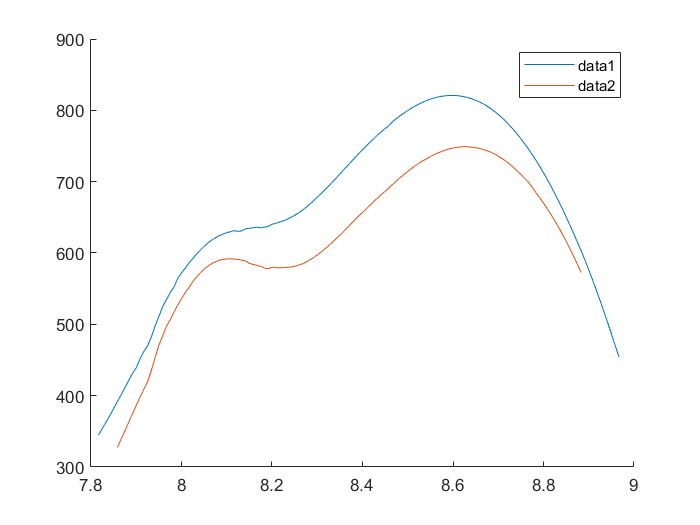

clf
hold on
% plot(time, squeeze(trajectories(2,3,:)))
% plot(time, squeeze(trajectories(3,3,:)))
plot(time, squeeze(trajectories(4,axis,:)))
plot(time, squeeze(trajectories(5,axis,:)))
hold off
legend

point1 = squeeze(trajectories(4,1:3,:));
point1 = point1(1:3, :);
point2 = squeeze(trajectories(5,1:3,:));
point2 = point2(1:3, :);

axis = 3

axis = 3

clf
diff3 = point1(3, :) - point2(3,:);
diff2 = point1(2, :) - point2(2,:);
diff1 = point1(1, :) - point2(1,:);

mag = vecnorm(point1(:,:) - point2(:,:));

mag =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


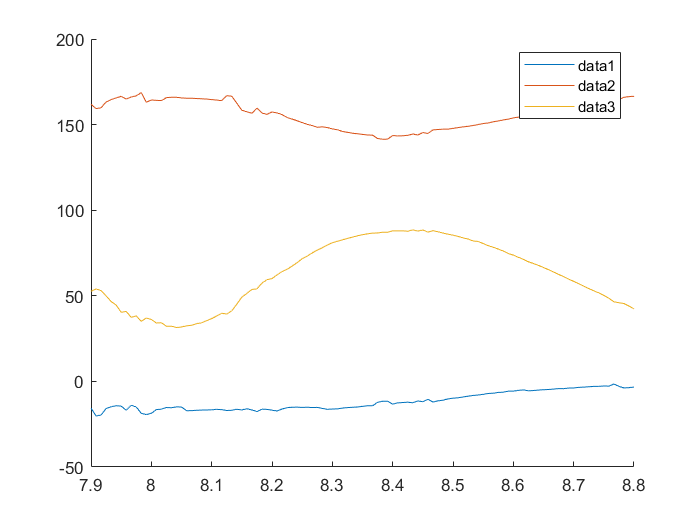

hold on
% plot(time, squeeze(trajectories(2,3,:)))
% plot(time, squeeze(trajectories(3,3,:)))
plot(time, diff1)
plot(time, diff2)
plot(time, diff3)
hold off
legend
xlim([7.9,8.8])

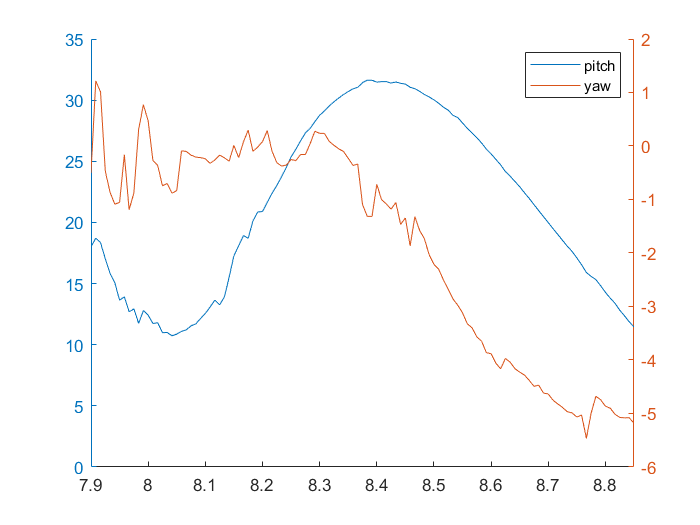

clf
hold on
xlim([7.9, 8.85])
yyaxis left
ylim([0,35])
plot(time,atand(diff3./diff2), 'DisplayName', "pitch")

yyaxis right
plot(time,atand(diff2./diff1)+84, 'DisplayName', "yaw")
hold off
legend

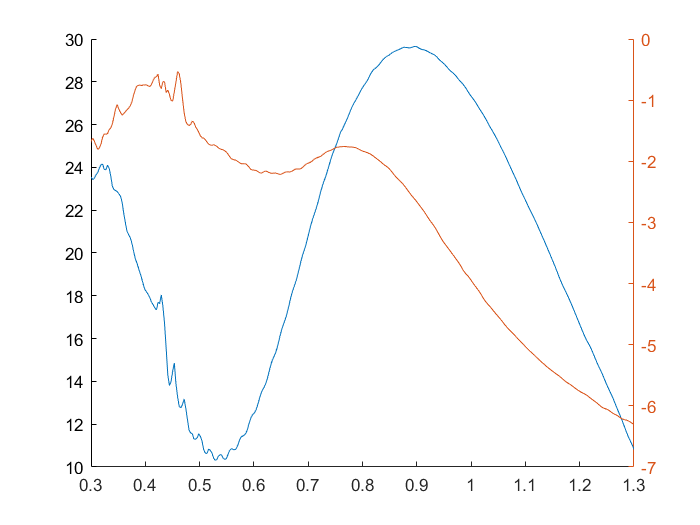

clf
time_imu = (0:1:size(imu_data,1)-1)/333;
imu = eulerd(a,'XYZ','frame');
hold on
xlim([0.3, 1.3])
plot(time_imu(100:550),imu(100:550,1))
yyaxis right
plot(time_imu(100:550),imu(100:550,3))